addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\ExtractClouds");

tic
pathname="C:\Users\agori\Documents\MATLAB\MSc\bigfiles\p3\";
[all_clouds, fnames] =rosGetRaw(pathname);
[minsz, testout] = getMinSz(all_clouds,fnames);

             Filenames             NClouds
    ___________________________    _______

    {'2022-07-23-21-13-51.bag'}      321  
    {'2022-07-23-21-17-10.bag'}      225  
    {'2022-07-23-21-18-58.bag'}      295  
    {'2022-07-23-21-21-48.bag'}      234  
    {'2022-07-23-21-23-08.bag'}      206  
    {'2022-07-23-21-25-26.bag'}      178  
    {'2022-07-23-21-28-10.bag'}      100  
    {'2022-07-23-21-30-11.bag'}       80  
    {'2022-07-23-21-32-03.bag'}      159  

Min size=80


toc

Elapsed time is 17.552325 seconds.


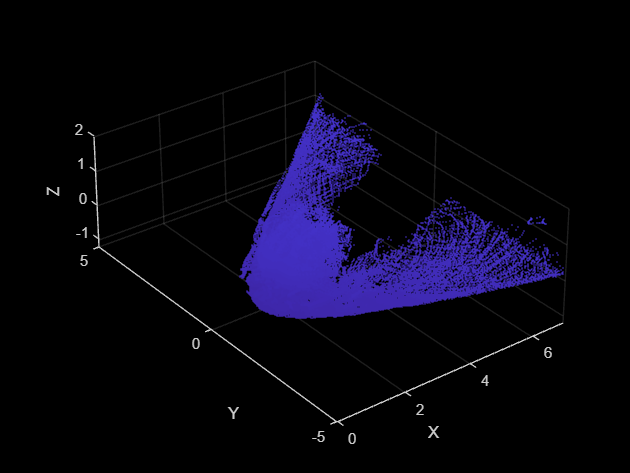

pcshow(testout,"AxesVisibility","on");
xlabel('X');
ylabel('Y');
zlabel('Z');

z_roi=[-inf,2];
y_roi=[-5,5];
x_roi=[0,7];

roi=[x_roi,y_roi,z_roi];
zlim(z_roi);
ylim(y_roi);
xlim(x_roi);

tic
arrLiDAR=cropMergeDownsample(roi,50,0.01,all_clouds(2:end));
toc

Elapsed time is 17.277176 seconds.


scanOrder='HABCDGFE';
arrLiDAR_ordered=reorderPointCloud(arrLiDAR,scanOrder);


% arrLiDAR=arrLiDAR_ordered;
% croppedClouds=arrLiDAR;
% arrShifted=arrLiDAR;
% croppedRotated=arrLiDAR;
% for k=1:8
%     %align floor
%     [floorAlign,tform]=alignFloorTform(arrLiDAR(k));
%     invTform = invert(tform);
%     %crop floor out
%     [sortedPOI,arrIndex,palletIndex,floorIndex,surfIndex] = normsAnalysis(floorAlign);
%     croppedClouds(k)=cropCloud(floorAlign,[-inf,inf],[-inf,inf],[sortedPOI(floorIndex+1)+0.02,inf]);
%     croppedRotated(k)=pctransform(croppedClouds(k),invTform);
% end

arrLiDAR=arrLiDAR_ordered;
croppedClouds=arrLiDAR;
croppedRotated=arrLiDAR;
floorTforms = cell(8,1);
%remove floor points for each arrCloudTrans
for k=1:8
    [floorAlign,tform]=alignFloorTform(arrLiDAR_ordered(k));
    floorTforms{k}=tform;
    invTform = invert(tform);
    %crop floor out
    [sortedPOI,arrIndex,palletIndex,floorIndex,surfIndex] = normsAnalysis(floorAlign);
    croppedClouds(k)=cropCloud(floorAlign,[-inf,inf],[-inf,inf],[sortedPOI(floorIndex+1)+0.02,inf]);
    croppedRotated(k)=pctransform(croppedClouds(k),invTform);
end

totalClouds=pccat(croppedClouds);
totalRotated=pccat(croppedRotated);

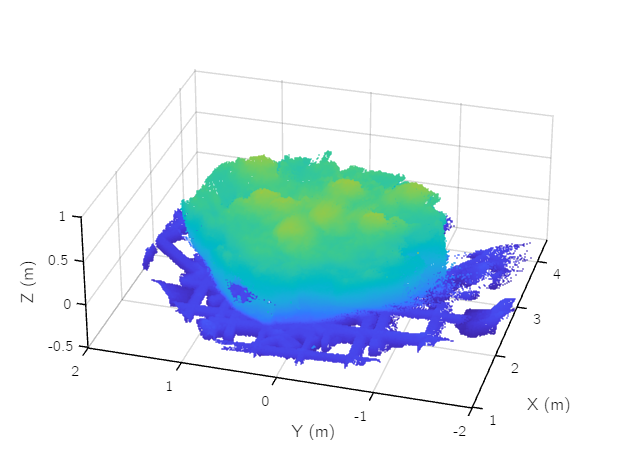

pcDisplay(totalClouds);
xlim([1,4.5]);
ylim([-2,2]);

z_roi=[-inf,inf];
y_roi=[-2,2];
x_roi=[1,4.5];

roi=[x_roi,y_roi,z_roi];
arrLiDARprocessed=cropClouds(croppedClouds,roi);

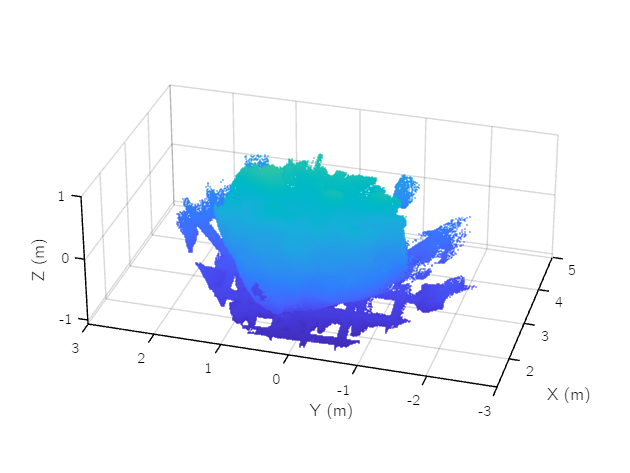

pcDisplay(totalRotated);
zlim([-inf,1]);
ylim([-3,3]);
xlim([1.25,5])


roi=[[1.25,5],[-3,3],[-inf,1]];
arrLiDAR_rotated=cropClouds(croppedRotated,roi);

addpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\CoarseAlignment");

%arrTforms=extractALNtransform("C:\Users\agori\Documents\MATLAB\MSc\CRUISE-DATA\A-Haligned.aln");
%arrTforms=extractALNtransform("C:\Users\agori\Documents\MATLAB\MSc\CRUISE-DATA\A-H2aligned.aln");

arrTformsRigid=extractALNtransformRigid("C:\Users\agori\Documents\MATLAB\MSc\CRUISE-DATA\A-H2aligned.aln");

C_RL = [0, 0, -1, 0;
        -1, 0, 0, 0;
        0, 1, 0, 0;
        0, 0, 0, 1];

C_LR = C_RL';  
arrTformsTotal = cell(1, 8);
arrCloudTrans = repmat(pointCloud(zeros(0,3)), 8, 1);

for i = 1:8
    arrTformsTotal{i} = rigidtform3d(C_RL * arrTformsRigid{i} * C_LR);
    arrCloudTrans(i)=pctransform(arrLiDAR_rotated(i), arrTformsTotal{i});
end

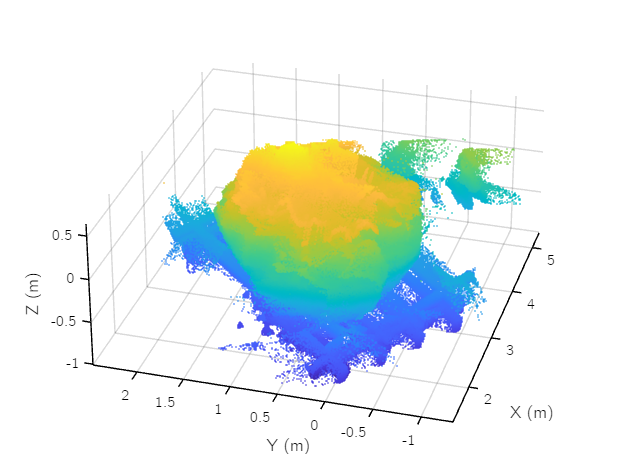

totalTrans=pccat(arrCloudTrans);
pcDisplay(totalTrans);

%saveClouds(arrCloudTrans,"C:\Users\agori\Documents\MATLAB\MSc\P3clean_Before\","Pancake3");

%saveClouds(arrCloudTrans,"C:\Users\agori\Documents\MATLAB\MSc\P3processing-clean\Pancake3_Before\","Pancake3");
saveClouds(arrCloudTrans,"C:\Users\agori\Documents\MATLAB\MSc\P3processing-clean\Pancake3_Before_Clean\","Pancake3");

save("C:\Users\agori\Documents\MATLAB\MSc\P3processing-clean\Pancake3_Before_Clean\P3rawExtract.mat", "floorTforms", "arrCloudTrans")